# `Лабораторная работа № 2 `

## `Вариант № 3`

### `Ход работы`

#### `Инициализация коеф варианта и построение графика.`

`W- весовой коэффициент`

W = 2

W = 2

`P– коэффициент смещения.`

p = -8

p = -8

x = -10:1:10

x =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


`Формула прямой y = W * x + p`

y = W .* x + p

y =    -28   -26   -24   -22   -20   -18   -16   -14   -12   -10    -8    -6    -4    -2     0     2     4     6     8    10    12


`График функции прямой `

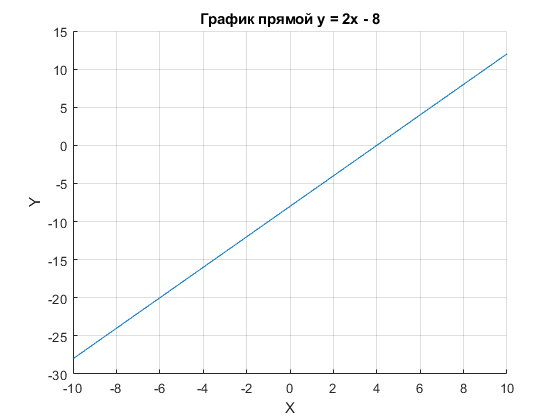

plot(x,y),grid on ,box off , xlabel("X"),ylabel("Y"),title("График прямой y = 2x - 8");

#### `Формирование 2х множеств точек: 10 черных и 10 белых. Формирование обучающей выборки на основе координат точек.`

`Координаты 10 черных точек `

points_X_Black = [-9 -8 -7 -6 -5 -3 -2 -1 1 2]

points_X_Black =     -9    -8    -7    -6    -5    -3    -2    -1     1     2


points_Y_Black = [-30 -28 -25 -23 -25 -20 -28 -27 -22 -20]

points_Y_Black =    -30   -28   -25   -23   -25   -20   -28   -27   -22   -20


`Координаты 10 белых точек`

points_X_White = [-9 -8 -7 -6 -5 -3 -2 -1 1 2]

points_X_White =     -9    -8    -7    -6    -5    -3    -2    -1     1     2


points_Y_White = [-20 -14 -15 -10 -8 -7 -2 0 5 10]

points_Y_White =    -20   -14   -15   -10    -8    -7    -2     0     5    10


`Матрица координат `

P = [points_X_Black points_X_White;points_Y_Black points_Y_White]

P =     -9    -8    -7    -6    -5    -3    -2    -1     1     2    -9    -8    -7    -6    -5    -3    -2    -1     1     2
   -30   -28   -25   -23   -25   -20   -28   -27   -22   -20   -20   -14   -15   -10    -8    -7    -2     0     5    10


`T – одномерный массив, определяет к какому множеству относятся точки. `

`Принято для точек, лежащих выше прямой («белых») указывать 1, а для точек ниже прямой («черных») – указывать 0. Количество элементов массива T равно количеству столбцов массива P и «цветовая принадлежность» указывается в том же порядке, что и координаты точек в массиве P`

T = [0 0 0 0 0 0 0 0 0 0 ...
    1 1 1 1 1 1 1 1 1 1]

T =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


`Построение графика функции и добавление на него множест точек`

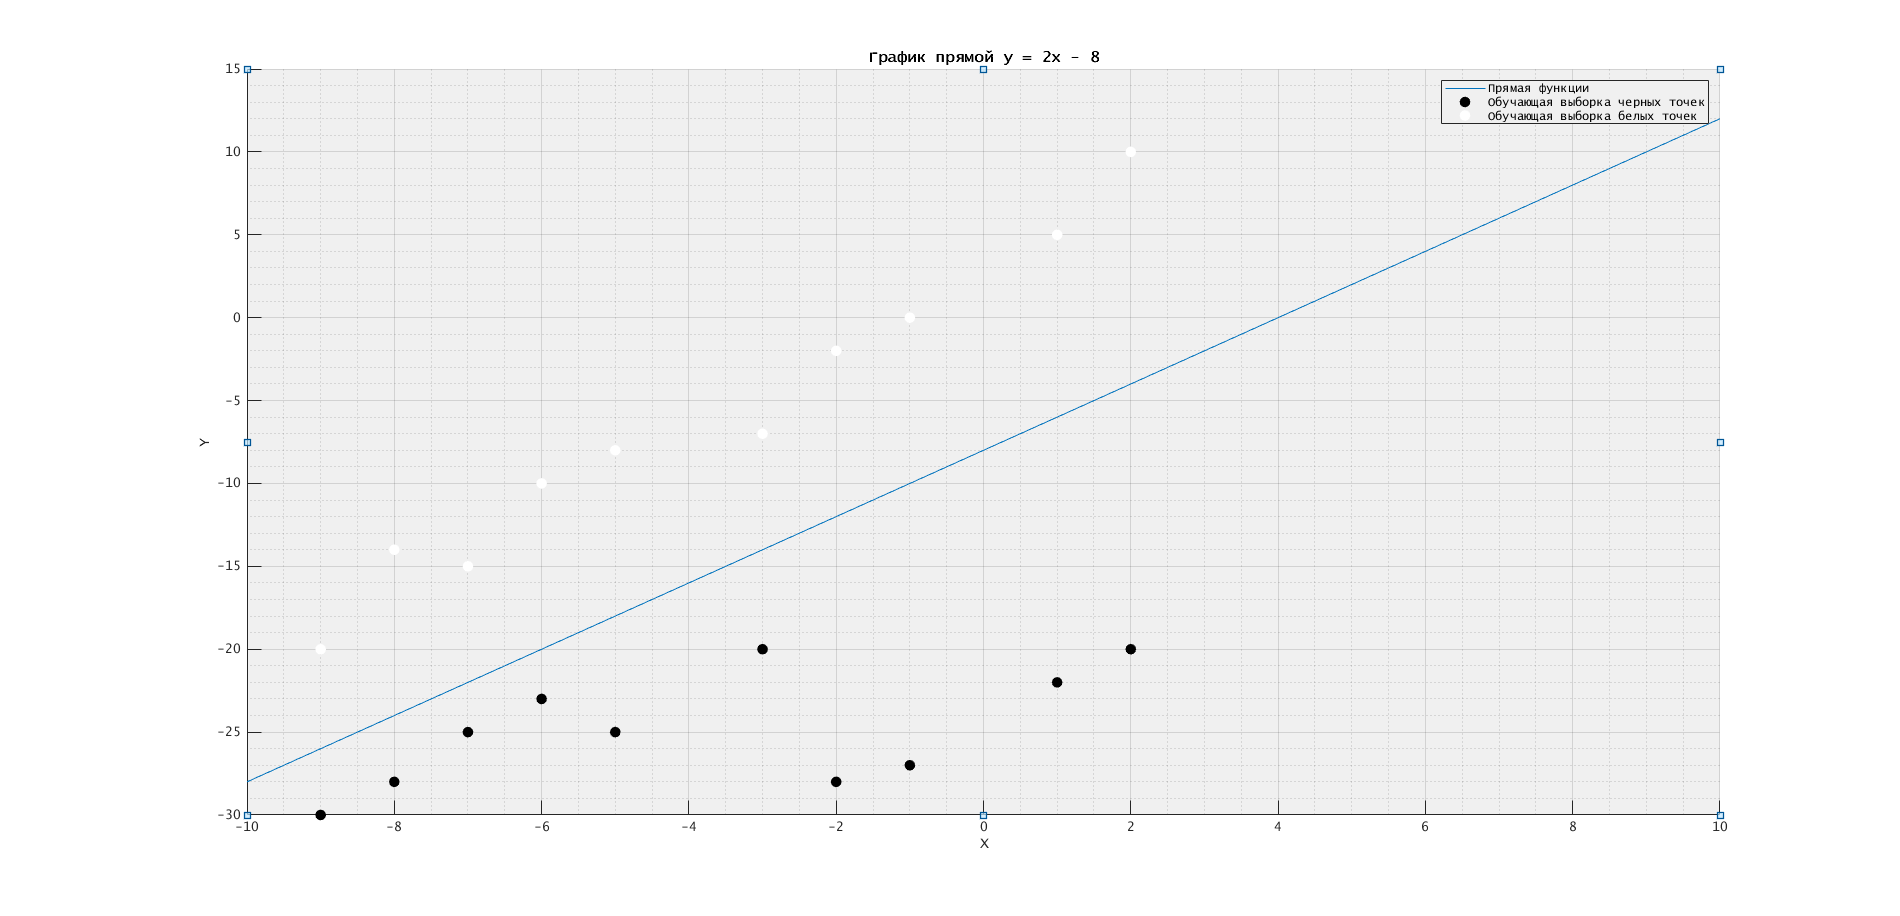

% Create figure
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Create plot
plot(x,y,'DisplayName','Прямая функции');

% Create scatter
scatter(points_X_Black,points_Y_Black,...
    'DisplayName','Обучающая выборка черных точек',...
    'MarkerEdgeColor',[0 0 0],...
    'LineWidth',2,...
    'MarkerFaceColor',[0 0 0]);

% Create scatter
scatter(points_X_Black,points_Y_White,...
    'DisplayName','Обучающая выборка белых точек',...
    'MarkerEdgeColor',[1 1 1],...
    'LineWidth',2,...
    'MarkerFaceColor',[1 1 1]);

% Create ylabel
ylabel('Y','FontName','Lucida Console');

% Create xlabel
xlabel('X','FontName','Lucida Console');

% Create title
title('График прямой y = 2x - 8');

grid(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'Color',[0.941176470588235 0.941176470588235 0.941176470588235],...
    'FontName','Lucida Console','FontSize',10,'XMinorGrid','on','YMinorGrid',...
    'on');
% Create legend
legend(axes1,'show')
figurepalette(figure1);

#### `Вывести документацию к команде newp и ознакомится с примером`

help newp

 newp Create a perceptron.
 
  Obsoleted in R2010b NNET 7.0.  Last used in R2010a NNET 6.0.4.
 
   Syntax
 
     net = newp(p,t,tf,lf)
 
   Description
 
     Perceptrons are used to solve simple (i.e. linearly
     separable) classification problems.
 
     NET = newp(P,T,TF,LF) takes these inputs,
       P  - RxQ matrix of Q1 representative input vectors.
       T  - SxQ matrix of Q2 representative target vectors.
       TF - Transfer function, default = 'hardlim'.
       LF - Learning function, default = 'learnp'.
     Returns a new perceptron.
 
     The transfer function TF can be HARDLIM or HARDLIMS.
     The learning function LF can be LEARNP or LEARNPN.
 
   Examples
 
     This code creates a perceptron layer with one 2-element
     input (ranges [0 1] and [-2 2]) and one neuron. (Supplying
     only two arguments to newp results in the default perceptron
     learning function LEARNP being used.)
 
       net = newp([0 1; -2 

#### `Создание однослойного персептрона с 2мя входами и 1м выходом. Обучение его на сформированных векторах с 10 шагами обучения.`

p_3 = newp(P,T);
p_3.adaptParam.passes = 10;
p_3 = train(p_3,P,T);

#### `Проверка правильности обучения на обучающей выборке.`

sim(p_3,P);

#### `Формирование новой разделяющей прямой после обучения ней`

plotpv(P,T); hold on
plotpc(p_3.IW{1,1},p_3.b{1}); hold on
y = W*P(1,:) + p

y =    -26   -24   -22   -20   -18   -14   -12   -10    -6    -4   -26   -24   -22   -20   -18   -14   -12   -10    -6    -4


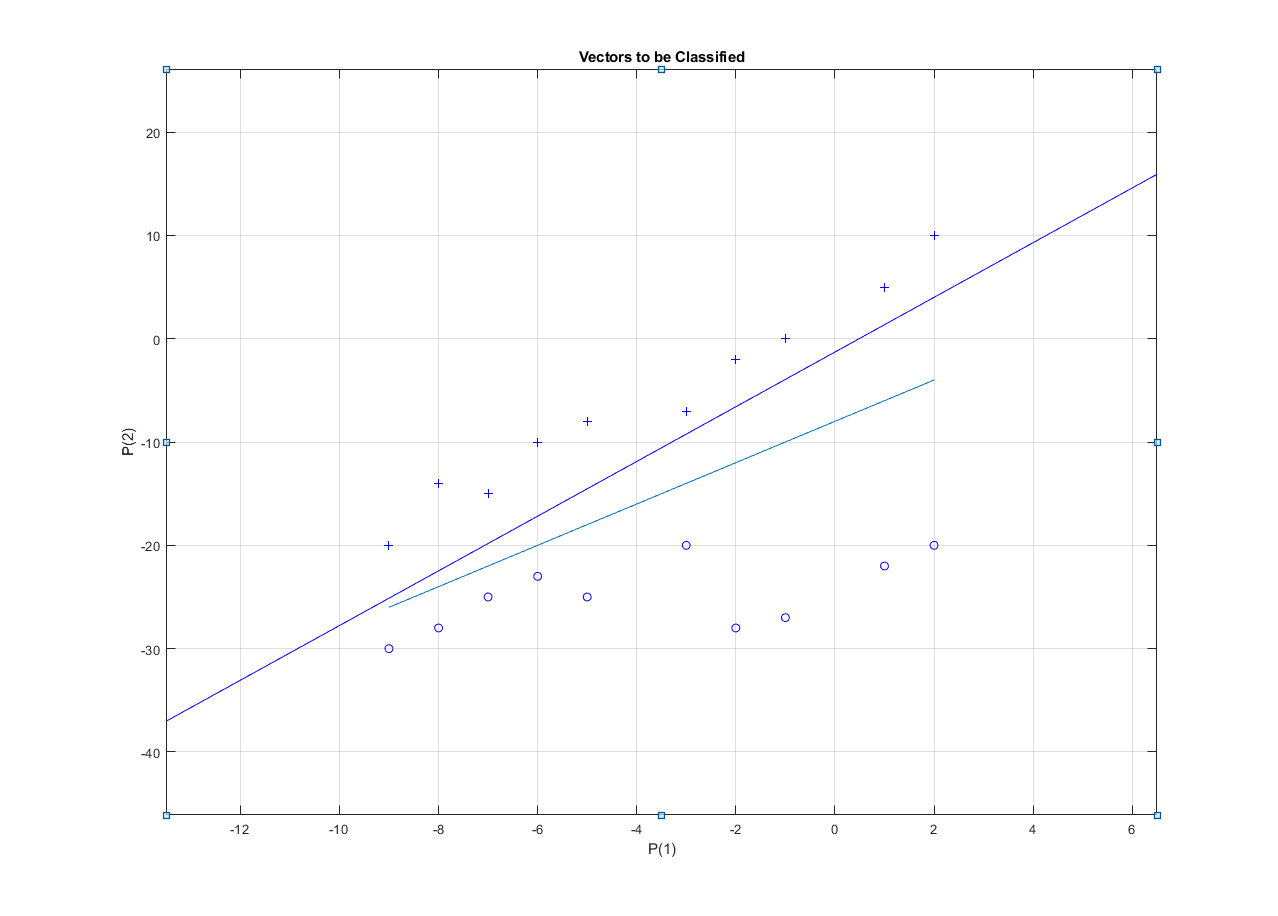

plot(P(1,:),y),grid;